# Wireless Project 1-Koorosh Moaveni Nejad-9923124

This program computes 1 set of 4 RSS from each of the four BS For the project, you need to augment the program:

    1. Implement the handoff algorithms that use RSS1,2,3,4 as inputs

    2. Include a loop so that you can have 100 sets of the 4 RSS

    (Hint: RSS of different sets only differ due to the random variable of shadow fading)

    3. In the loop store variable data between iterations  that will be used to make the final histograms/PDFs

# Part 1. RSS Calculations

clc;
clear;

% Declare the various variables used for distances
R = 250;
L = 2 * R;
speed = 1;
sample_time = 0.1;
step_distance = speed * sample_time;
g = 150;
min_distance = sqrt(g);
max_distance = L - sqrt(g);
d1 = [min_distance:step_distance:max_distance];
d2 = L - d1;
d3 = abs(R - d1);
d4 = abs(R - d1);
Ns = length(d1);
% Declare variables and compute RSS
% Part 1: Computations independant of the random variable
% for shadow fading
Pt = 20;
Po = 38;
grad1 = 2;
grad2 = 2;
alpha = exp(-1/85);
sigma1 = sqrt(8);
sigma2 = sqrt(sigma1^2 * (1 - alpha^2));
RSS01 = Pt - Po - (10 * grad1 * log10(d1) + 10 * grad2 * log10(d1/g));
RSS02 = Pt - Po - (10 * grad1 * log10(d2) + 10 * grad2 * log10(d2/g));
RSS_corner = Pt - Po - (10 * grad1 * log10(R) + 10 * grad2 * log10(R/g));
RSS03 = RSS_corner - (10 * grad1 * log10(d3) + 10 * grad2 * log10(d3/g));
RSS04 = RSS_corner - (10 * grad1 * log10(d4) + 10 * grad2 * log10(d4/g));


for i=1:Ns
 if d3(i) < min_distance
 RSS03(i) = RSS_corner;
 end;
 if d4(i) < min_distance
 RSS04(i) = RSS_corner;
 end;
end;



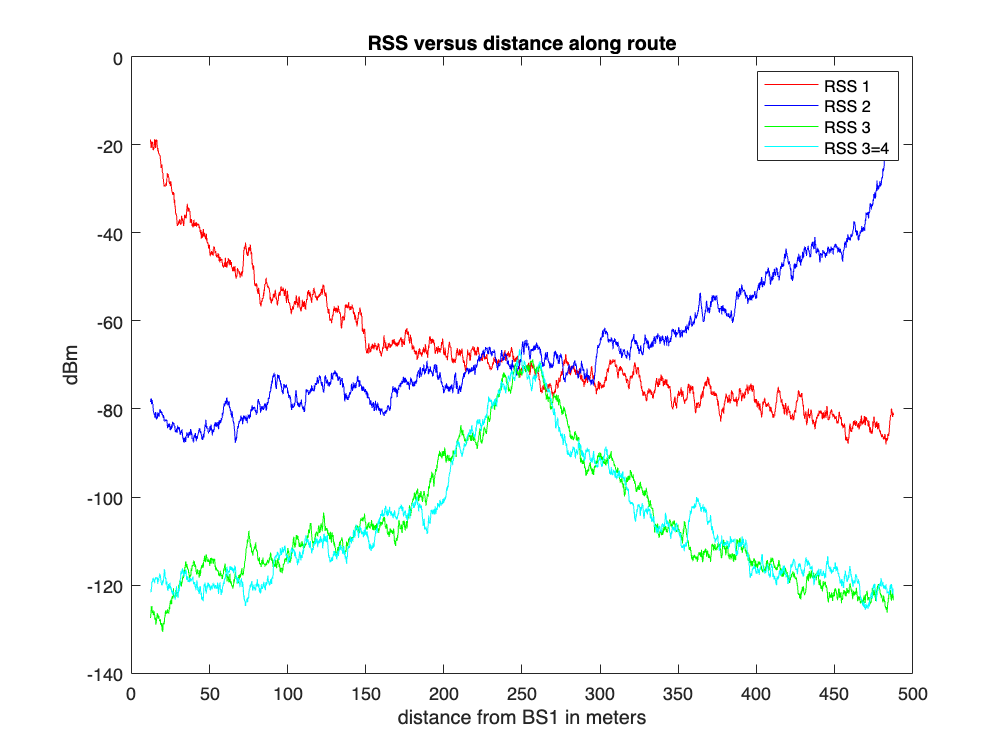

% Part 2: Adding the random variable for shadow fading
s1(1) = sigma1 * randn(1);
s2(1) = sigma1 * randn(1);
s3(1) = sigma1 * randn(1);
s4(1) = sigma1 * randn(1);
for i=2:Ns
 s1(i) = alpha * s1(i-1) + sigma2 * randn(1);
 s2(i) = alpha * s2(i-1) + sigma2 * randn(1);
 s3(i) = alpha * s3(i-1) + sigma2 * randn(1);
 s4(i) = alpha * s4(i-1) + sigma2 * randn(1);
end
RSS1 = RSS01 + s1;
RSS2 = RSS02 + s2;
RSS3 = RSS03 + s3;
RSS4 = RSS04 + s4;
% Plot the RSS values obtained
figure;
plot(d1, RSS1,'r')
hold on
plot(d1, RSS2,'b')
hold on
plot(d1, RSS3,'g')
hold on
plot(d1, RSS4,'c')
title('RSS versus distance along route')
xlabel('distance from BS1 in meters');
ylabel('dBm');
legend("RSS 1","RSS 2","RSS 3","RSS 3=4")

## Next we repeat the simulation 100 times to create a simple dataset.


for k=1:100

    s1(1) = sigma1 * randn(1);
    s2(1) = sigma1 * randn(1);
    s3(1) = sigma1 * randn(1);
    s4(1) = sigma1 * randn(1);
    for i=2:Ns
     s1(i) = alpha * s1(i-1) + sigma2 * randn(1);
     s2(i) = alpha * s2(i-1) + sigma2 * randn(1);
     s3(i) = alpha * s3(i-1) + sigma2 * randn(1);
     s4(i) = alpha * s4(i-1) + sigma2 * randn(1);
    end
    RSS1(k,:) = RSS01 + s1;
    RSS2(k,:) = RSS02 + s2;
    RSS3(k,:) = RSS03 + s3;
    RSS4(k,:) = RSS04 + s4;
end


# Part2. Handoff Algorithms Simulations

## Simple Rss

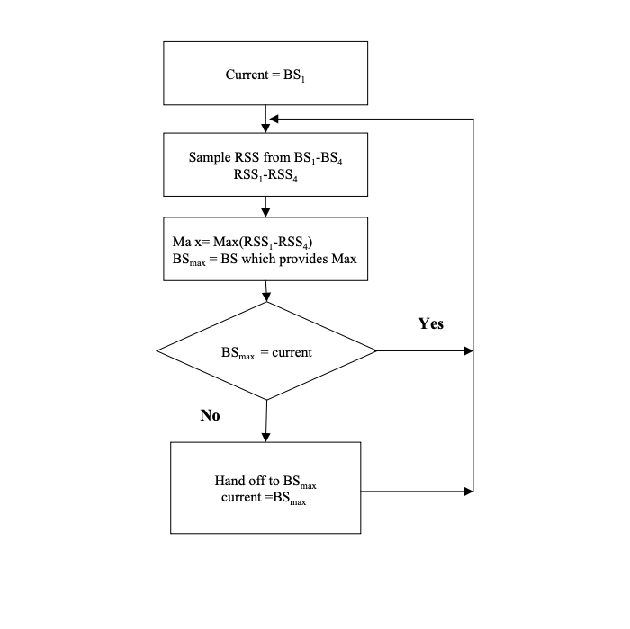

figure;
imshow("Simple Rss.png");

## Simple RSS Algorithm

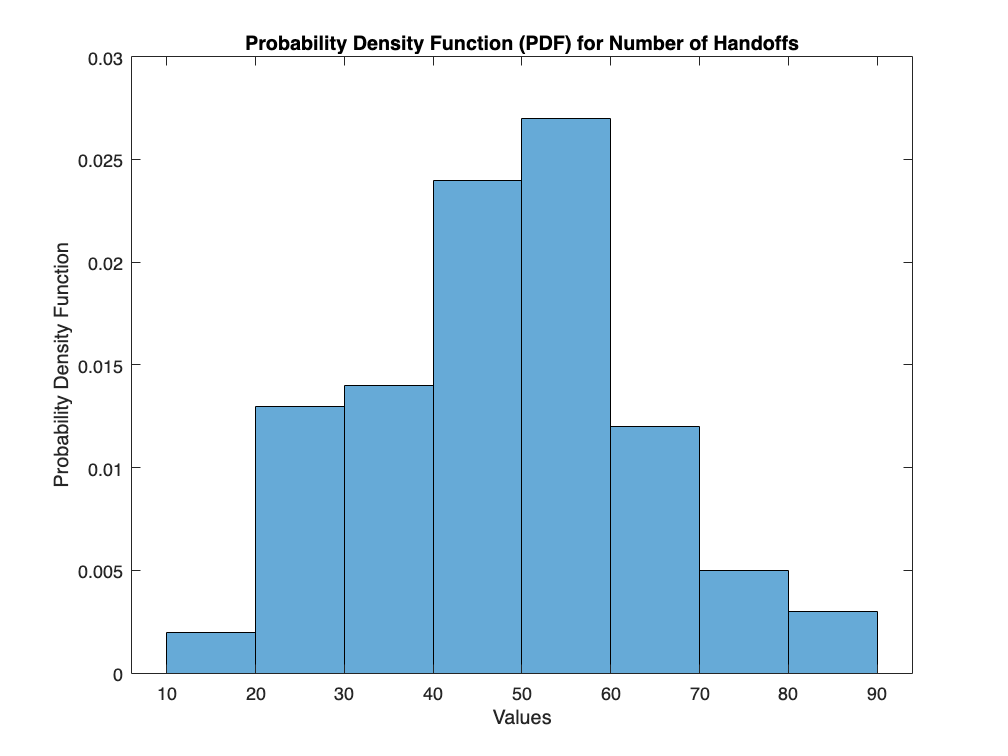

Handoff_loc1=[];
Handoff_num1(k)=0;
% Handoff_loc1(k)=0;
current1=[];
current1(1,1)=RSS1(1,1);
for k=1:100
    for i=1:length(d1)
        current1(k,i)=max([RSS1(k,i),RSS2(k,i),RSS3(k,i),RSS4(k,i)]);
        current1(k,i)=find([RSS1(k,i),RSS2(k,i),RSS3(k,i),RSS4(k,i)]==current1(k,i));
       if (i>1) && ~(current1(k,i)==current1(k,i-1))
           Handoff_num1(k)=Handoff_num1(k)+1;
           Handoff_loc1(k,Handoff_num1(k))=d1(i);
       end
    end
end

% Plot PDF of number of handoffs using histogram
figure;
histogram(Handoff_num1, 'Normalization', 'pdf');
xlabel('Values');
ylabel('Probability Density Function');
title('Probability Density Function (PDF) for Number of Handoffs');  

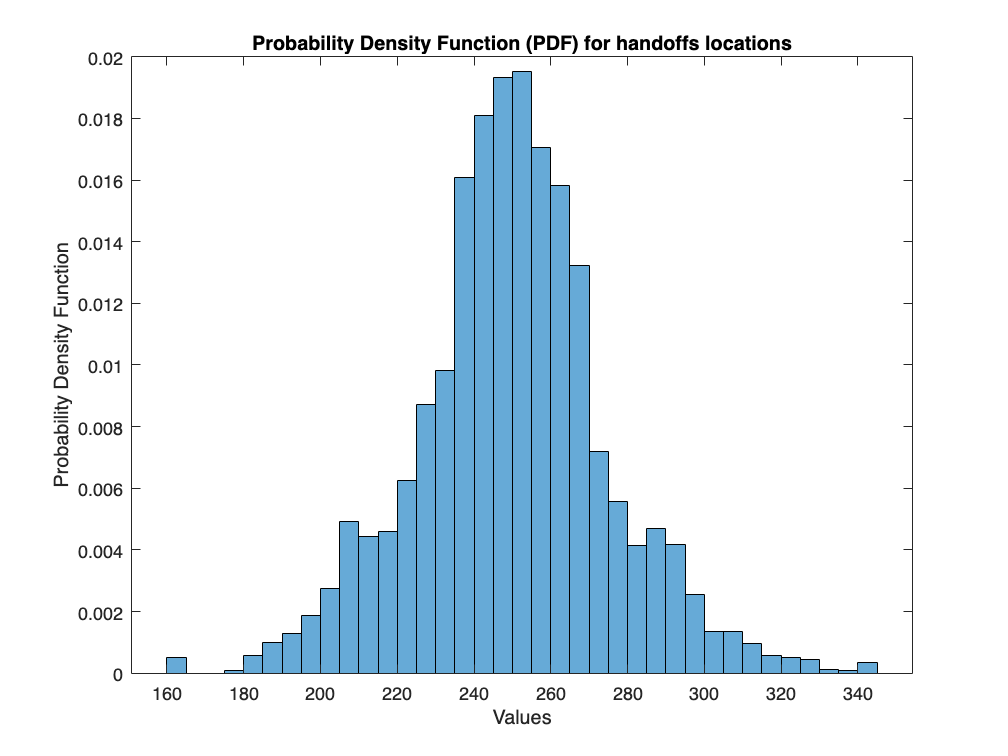


% Plot PDF of handoffs' locations using histogram
% All zero values generated with this algorithm should be omitted so...
non_zero_indices = Handoff_loc1 ~= 0;
Handoff_loc1 = Handoff_loc1(non_zero_indices);

% Use logical indexing to extract non-zero elements

figure;
histogram(Handoff_loc1, 'Normalization', 'pdf');
xlabel('Values');
ylabel('Probability Density Function');
title('Probability Density Function (PDF) for handoffs locations'); 

### Describtion:

As we expected, probability function of handoff loacation is considerably dense in the values corresponding to the middle of the path.

## RSS With Threshold 

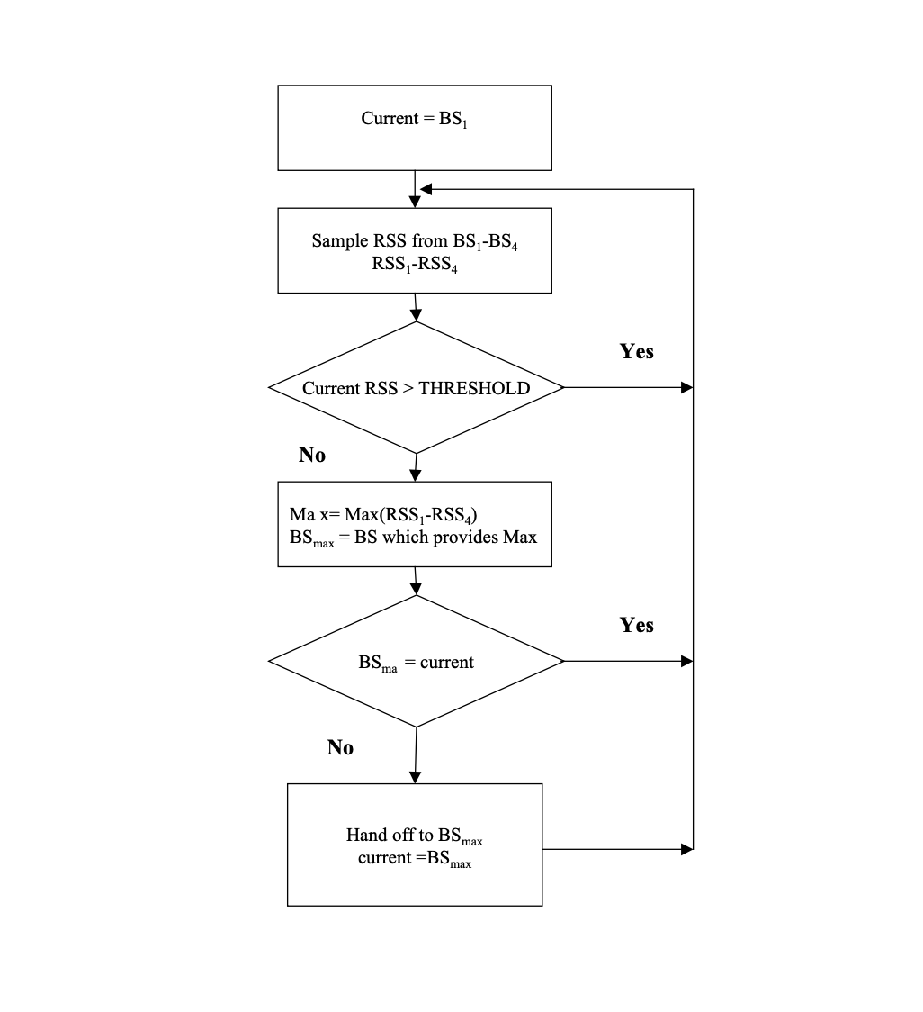

figure;
imshow("RSS With Threshold.png");

## RSS With Threshold Algorithm ( Threshold= -68 dbm )

Threshold=-68; %threshold ( dbm )
RSS={RSS1,RSS2,RSS3,RSS4};
current2=zeros(100,length(d1));
Handoff_loc2=[];
for k=1:100
    current2(k,1)=1;
    Handoff_num2(k)=0;
    for i=1:length(d1)
        if RSS{current2(k,i)}(k,i)>= Threshold
           current2(k,i+1)=current2(k,i);
        else
            current2(k,i)=max([RSS1(k,i),RSS2(k,i),RSS3(k,i),RSS4(k,i)]);
            current2(k,i)=find([RSS1(k,i),RSS2(k,i),RSS3(k,i),RSS4(k,i)]==current2(k,i));
            current2(k,i+1)=current2(k,i);
        end
        if (i>1) && ~(current2(k,i)==current2(k,i-1))
            Handoff_num2(k)=Handoff_num2(k)+1;
            Handoff_loc2(k,Handoff_num2(k))=d1(i);
        end
    end
end


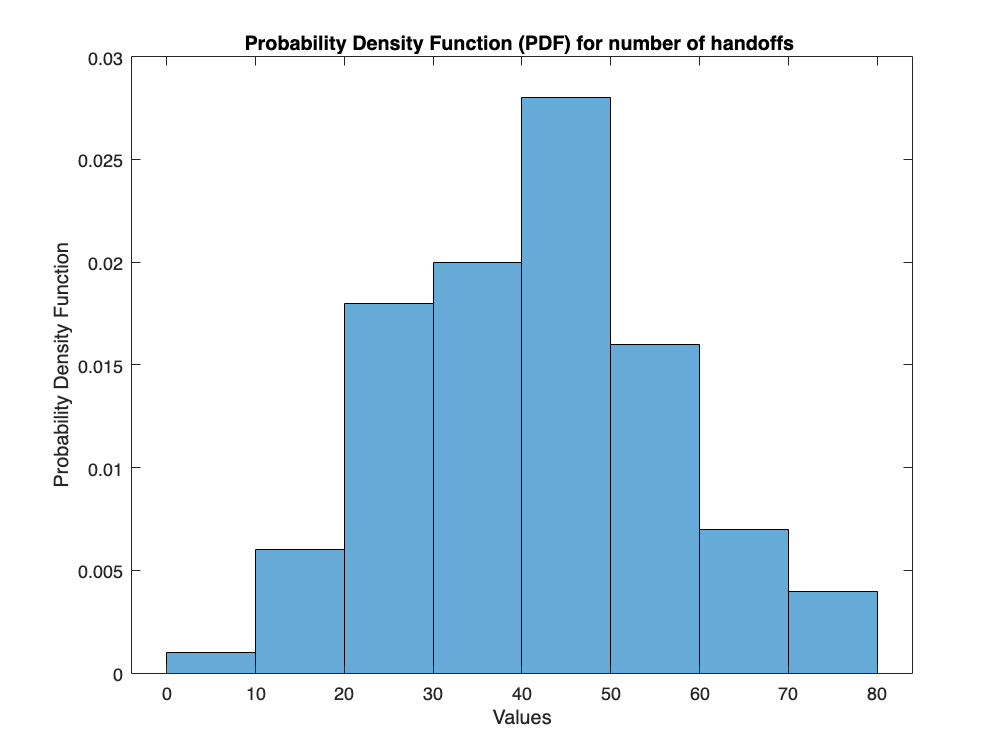

 % Plot PDF of number of handoffs using histogram
figure;
histogram(Handoff_num2, 'Normalization', 'pdf');
xlabel('Values');
ylabel('Probability Density Function');
title('Probability Density Function (PDF) for number of handoffs '); 

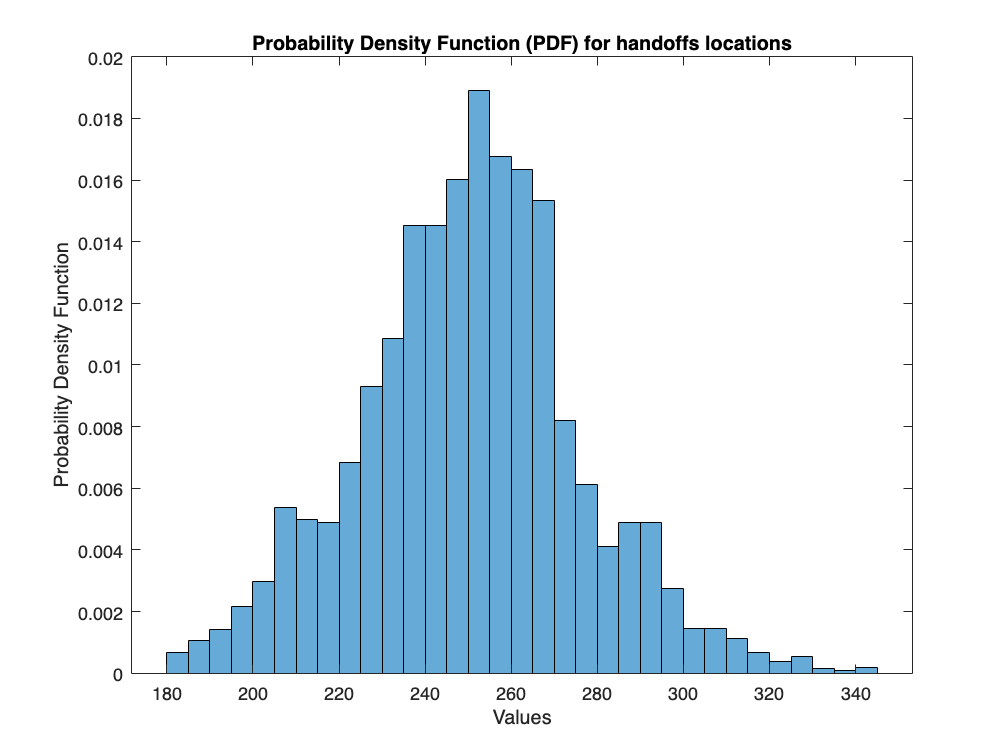

% Plot PDF of handoffs' locations using histogram
% All zero values generated with this algorithm should be omitted so...
non_zero_indices2 = Handoff_loc2 ~= 0;
Handoff_loc2 = Handoff_loc2(non_zero_indices2);
figure;
histogram(Handoff_loc2, 'Normalization', 'pdf');
xlabel('Values');
ylabel('Probability Density Function');
title('Probability Density Function (PDF) for handoffs locations');

## RSS and Hysteresis

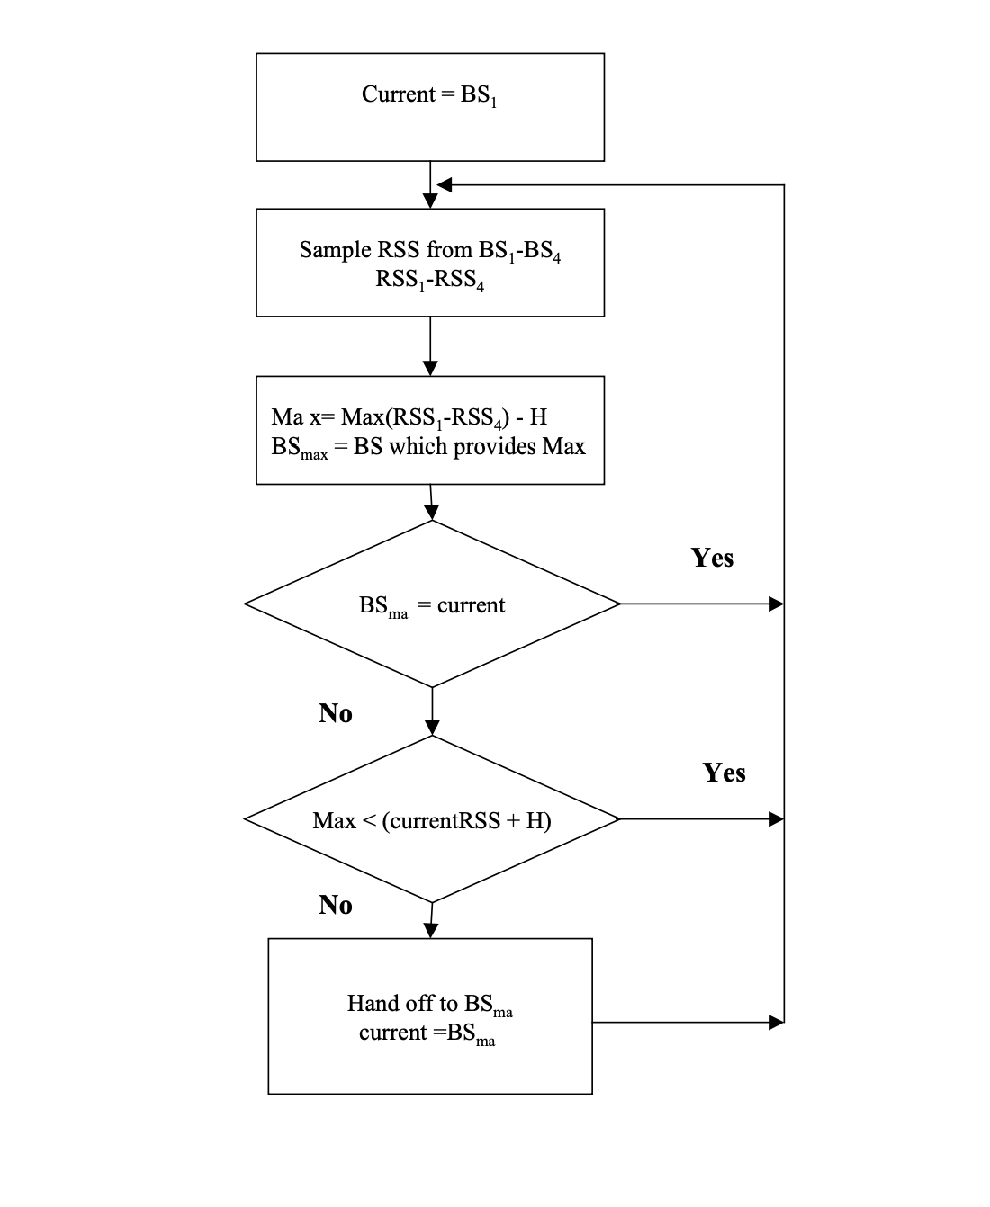

figure;
imshow("RSS and Hysteresis.png");

## RSS and Hysteresis Algorithm

current3=zeros(100,length(d1));
Handoff_loc3=[];
Handoff_num3=[];
H=5; %Hysteresis = 5 dbm

for k=1:100
    current3(k,1)=1;
    Handoff_num3(k)=0;

    for i=1:length(d1)
        if RSS{current3(k,i)}(k,i) + H >= max([RSS1(k,i),RSS2(k,i),RSS3(k,i),RSS4(k,i)])
           current3(k,i+1)=current3(k,i);
        else
            current3(k,i)=max([RSS1(k,i),RSS2(k,i),RSS3(k,i),RSS4(k,i)]);
            current3(k,i)=find([RSS1(k,i),RSS2(k,i),RSS3(k,i),RSS4(k,i)]==current3(k,i));
            current3(k,i+1)=current3(k,i);
        end    
        if (i>1) && ~(current3(k,i)==current3(k,i-1))
            Handoff_num3(k)=Handoff_num3(k)+1;
            Handoff_loc3(k,Handoff_num3(k))=d1(i);           
        end    
    end
end

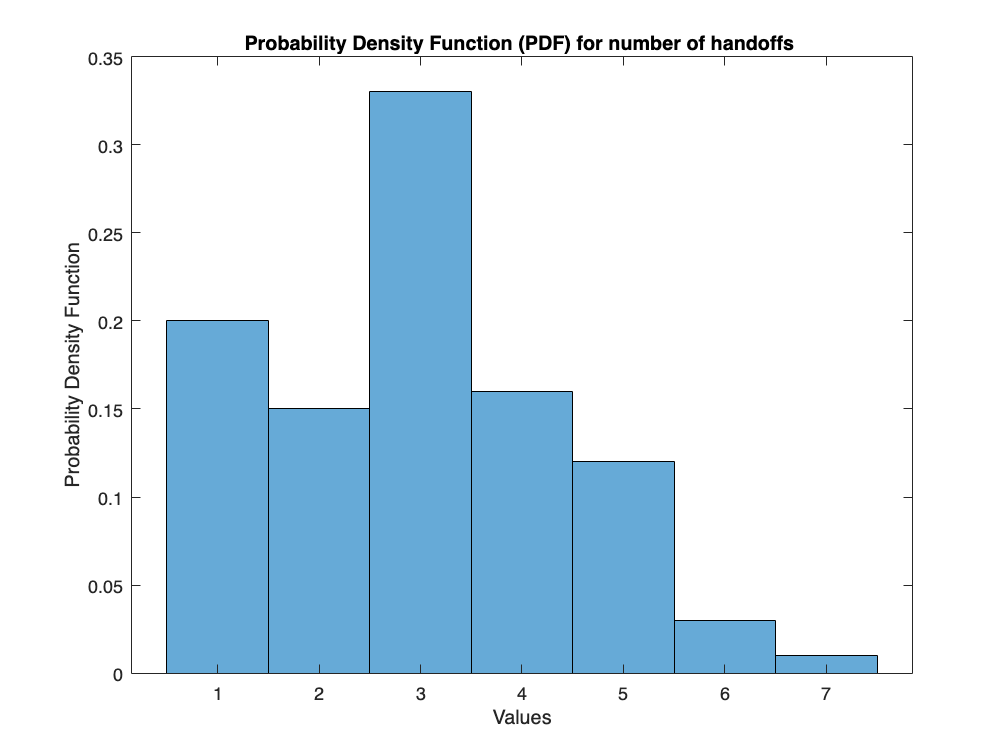

% Plot PDF of number of handoffs using histogram
figure;
histogram(Handoff_num3, 'Normalization', 'pdf');
xlabel('Values');
ylabel('Probability Density Function');
title('Probability Density Function (PDF) for number of handoffs '); 

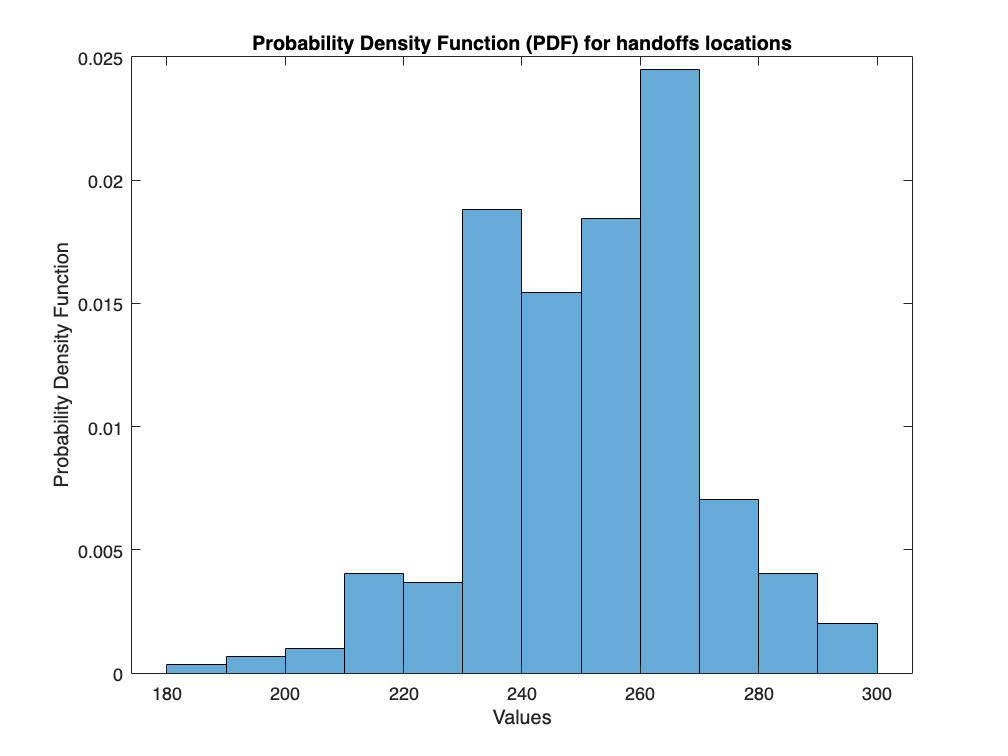

% Plot PDF of handoffs' locations using histogram
% All zero values generated with this algorithm should be omitted so...
non_zero_indices3 = Handoff_loc3 ~= 0;
Handoff_loc3 = Handoff_loc3(non_zero_indices3);
figure;
histogram(Handoff_loc3, 'Normalization', 'pdf');
xlabel('Values');
ylabel('Probability Density Function');
title('Probability Density Function (PDF) for handoffs locations');

## RSS And Hysteresis

figure;
imshow("RSS and Hysteresis.png");

current3=zeros(100,length(d1));
Handoff_loc4=[];
Handoff_num4=[];


for k=1:100
    current4(k,1)=1;
    Handoff_num4(k)=0;  
    for i=1:length(d1)
        if RSS{current4(k,i)}(k,i)>= Threshold
            current4(k,i+1)=current4(k,i);        
        elseif RSS{current4(k,i)}(k,i) + H >= max([RSS1(k,i),RSS2(k,i),RSS3(k,i),RSS4(k,i)])
            current4(k,i+1)=current4(k,i);    
        else           
            current4(k,i)=max([RSS1(k,i),RSS2(k,i),RSS3(k,i),RSS4(k,i)]);
            current4(k,i)=find([RSS1(k,i),RSS2(k,i),RSS3(k,i),RSS4(k,i)]==current4(k,i));
            current4(k,i+1)=current4(k,i);
        end
        if (i>1) && ~(current4(k,i)==current4(k,i-1))
            Handoff_num4(k)=Handoff_num4(k)+1;
            Handoff_loc4(k,Handoff_num4(k))=d1(i);
        end
    end
end

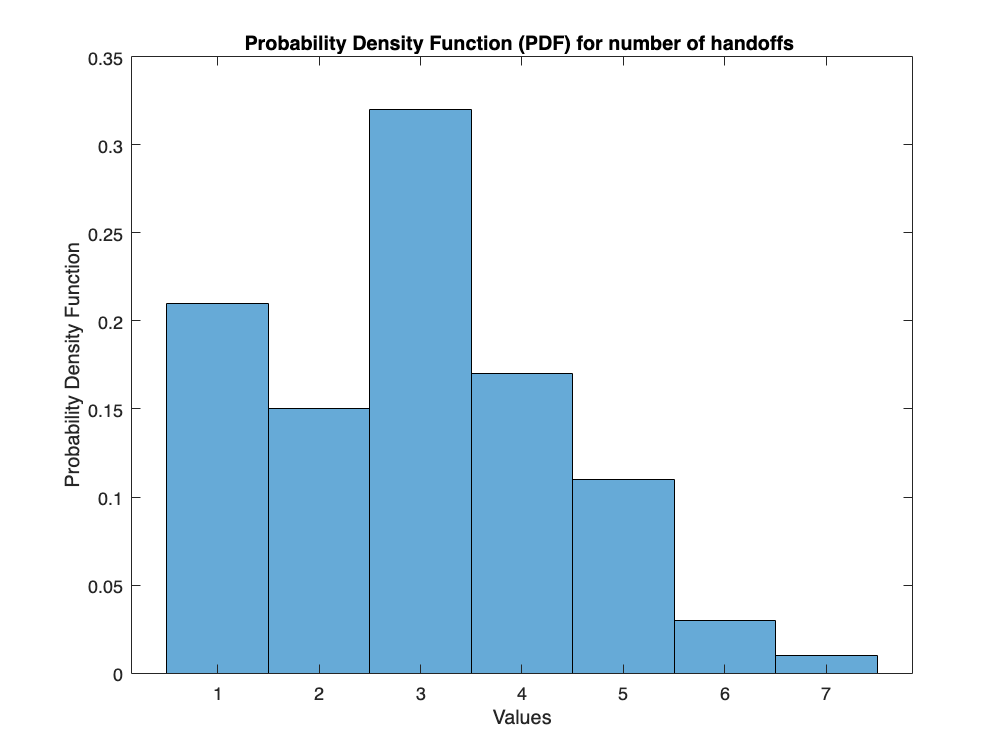

% Plot PDF of number of handoffs using histogram
figure;
histogram(Handoff_num4, 'Normalization', 'pdf');
xlabel('Values');
ylabel('Probability Density Function');
title('Probability Density Function (PDF) for number of handoffs '); 

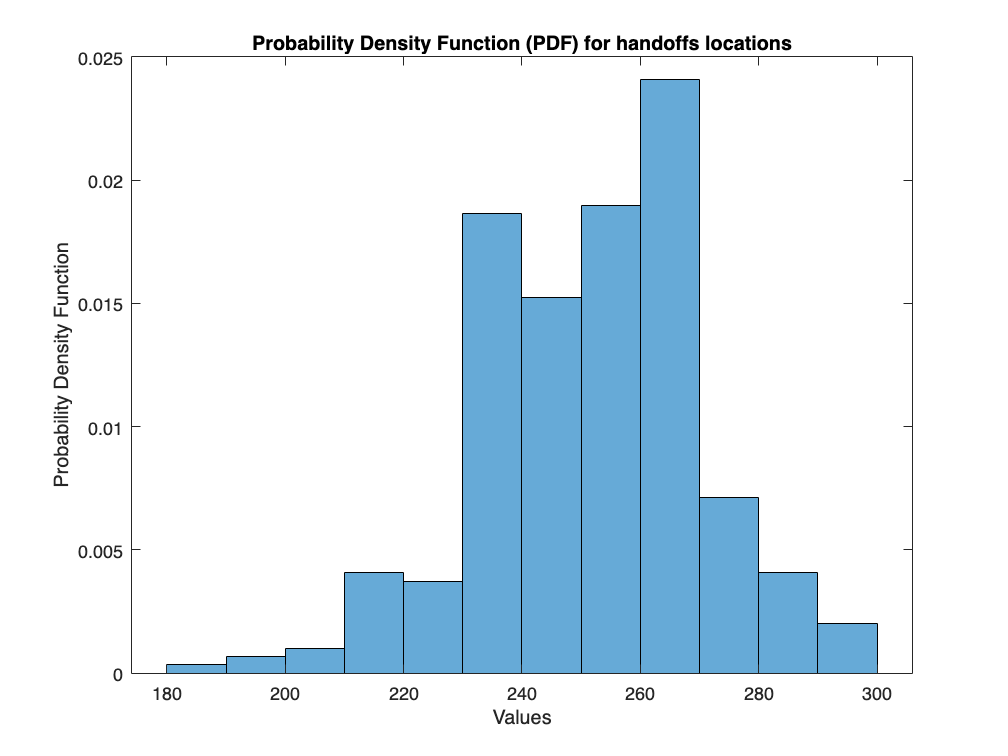

% Plot PDF of handoffs' locations using histogram
% All zero values generated with this algorithm should be omitted so...
non_zero_indices4 = Handoff_loc4 ~= 0;
Handoff_loc4 = Handoff_loc4(non_zero_indices4);
figure;
histogram(Handoff_loc4, 'Normalization', 'pdf');
xlabel('Values');
ylabel('Probability Density Function');
title('Probability Density Function (PDF) for handoffs locations');

# Conclusion

Comparing the histograms, it's obvious that first two algorithms ( SIMPLE RSS & RSS WITH THRESHOLD ) are likely to cause more handoffs. So in systems which number of handoffs should be seriously considered due to the high cost of calculations, this two methods are not rather efficient and well-suited. In such systems, We can use the last two approaches as the PDF for number of handoffs is aggregated in much less values.

As mentioned before, an ideal situation is when we only have one handoff in the half of the path. So all 4 mentioned methods showed satistying result for location of hanoff and met our predictions.

Simple RSS (Received Signal Strength):

- Conclusion: Simple RSS is a straightforward technique for estimating signal strength in wireless communication. It measures the power level of the received signal.

- Advantages:

- Simplicity: It's easy to implement and understand.

- Low Overhead: Minimal computational and processing overhead.

- Widespread Use: Many wireless devices and protocols utilize simple RSS for basic signal strength estimation.

- Disadvantages:

- Sensitivity to Interference: Susceptible to interference and noise, which can affect accuracy.

- Limited Information: Provides only a basic measure of signal strength without considering other factors like fading or multipath effects.

RSS with Threshold:

- Conclusion: RSS with threshold adds a decision-making component to simple RSS by comparing the received signal strength to a predefined threshold value.

- Advantages:

- Binary Decision: Helps in binary decisions (e.g., presence/absence of a signal) without requiring precise signal strength measurements.

- Reduced False Alarms: Can reduce false alarms by ignoring weak signals below the threshold.

- Disadvantages:

- Fixed Threshold: Vulnerable to changes in environmental conditions or signal propagation characteristics.

- Limited Flexibility: Lacks adaptability to varying signal conditions.

RSS with Hysteresis:

- Conclusion: RSS with hysteresis introduces a buffering mechanism around the threshold to prevent rapid state transitions in the presence of signal fluctuations.

- Advantages:

- Stability: Helps maintain stability by avoiding frequent state changes in borderline signal conditions.

- Noise Robustness: Reduces sensitivity to short-term signal variations and noise.

- Disadvantages:

- Increased Complexity: Adds complexity compared to simple threshold-based approaches.

- Delayed Response: May introduce delays in response to signal changes due to the buffering effect.

Threshold and Hysteresis:

- Conclusion: Combining both threshold and hysteresis techniques offers a compromise between simplicity and stability in signal detection.

- Advantages:

- Balanced Approach: Offers a balance between sensitivity to signal changes and stability against noise.

- Improved Reliability: Enhances reliability by reducing false alarms and missed detections.

- Disadvantages:

- Complexity: Requires more complex implementation compared to simple RSS or threshold-only approaches.

- Optimization Challenges: Tuning threshold and hysteresis parameters may require optimization efforts for different environments.

In summary, each technique offers a trade-off between simplicity, sensitivity, and robustness in signal detection, catering to different application requirements and environmental conditions. The choice depends on factors such as desired accuracy, reliability, and computational resources available.